# Getting the PSD of an AR model

## Introduction

In this tutorial you will learn how to estimate the true one-sided PSD of a univariate random process defined by an AR model. The PSD is a continuous function that depends on a frequency variable. This can be $f$ in Hz, $\omega$ in rad/s, the non dimensional sampled frequency $\tilde{f}$ that ranges from 0 to 0.5, etc. In this case, the computed PSD is $S^{AR}(f)$. This implies that a $\Delta t$ in seconds is assumed in the AR time series model.

The dataset employed in this tutorial is 'datasets/dataset_01_AR', which includes a restricted AR model.

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

delta_t = 0.05; % time step assumed for the AR time series model

N_f = 300;      % number of elements of the frequency vector


%%% Plot parameters
font_size       = 16;
figure_position = [0 0 1000 400];

Load the dataset. It consists of a restricted AR model. Check the fields required by function `get_S_AR`. For details related to the fields of these objects, see functions `initialise_AR`.

load dataset_01_AR AR

fprintf('j_vector is [%d, %d, %d] \n', AR.restricted_parameters.j_vector)

j_vector is [1, 2, 5] 


fprintf('a_vector is [%.1f, %.1f, %.1f] \n', AR.restricted_parameters.a_vector)

a_vector is [1.2, -0.5, 0.1] 


fprintf('b is %.1f \n',AR.restricted_parameters.b)

b is 0.5 


Initialise an `S `object with the fields required by function `get_S_AR`. In particular, define the frequency values in which the PSD is evaluated. This is done with linear scaling between 0 and $f_{max}$.

f_max       = 1/(2*delta_t);
f_vector    = linspace(0,f_max,N_f);

S0 = initialise_S('ind_var','f',...
                  'x_values',f_vector, ...
                  'x_max',f_max);

Compute the PSD of the AR model.

S_AR = get_S_AR(AR,S0);

Plot the obtained PSD.

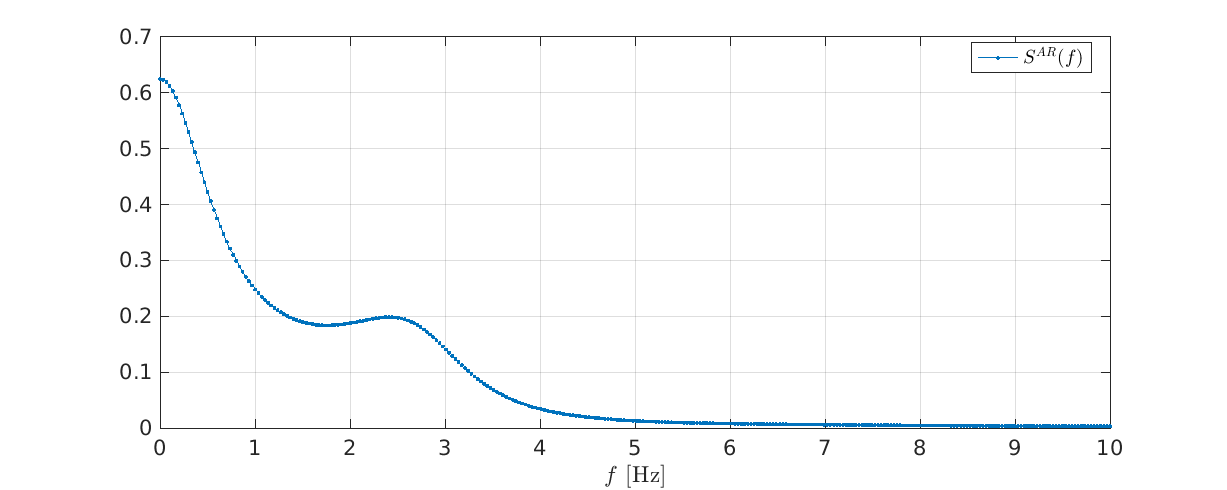

figure

x = S_AR.x_values;
y = S_AR.y_values;
plot(x,y,'.-')

grid on
legend({'$S^{AR}(f)$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$f$ [Hz]','Interpreter','latex')
set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

A nice check consists in verifying that the integral of the two-sided PSD, $S^{AR,2S}$, in the domain $[-f_{max}, f_{max}]$ corresponds to the variance of the process,

 
$$\int_{-f_{max}}^{f_{max}} S^{AR,2S}(f) \,\text{d}f = \gamma^{AR}[0].$$


Note that the two-sided PSD can be evaluated for negative frequencies, is symmetric, and that the one-sided PSD is twice the two-sided PSD, $S(f) = 2\cdot S^{2S}(f)$), thus,


$$\int_{-f_{max}}^{f_{max}} S^{AR,2S}(f) \,\text{d}f = \int_{0}^{f_{max}} S^{AR}(f) \,\text{d}f.$$


Compute the integral of the one-sided PSD between 0 and $f_{max}$.

psd_fun = @(f) interp1(S_AR.x_values,S_AR.y_values,f);
integral_PSD_AR = integral(psd_fun,0,f_max)

integral_PSD_AR = 0.9444

Compute the variance of the process (see tutorial '*T5_01_getting_gamma_from_AR*').

[gamma_fun] = initialise_gamma('M', 0); 
[gamma_fun] = get_gamma_AR (AR, gamma_fun);
variance_AR = gamma_fun.y_values

variance_AR = 0.9444

## Remarks

The final check described in this tutorial stems from the Wiener-Khinchin theorem, which states that the autocovariance function and the two-sided PSD are Fourier pairs: 


$$\gamma[m] = \int_{-f_{max}}^{f_{max}} S^{2S}(f) \cdot \text{exp}(j  \, 2 \pi f  \, m \, \Delta t) \text{d}f,$$
   

particularised for $m=0$.